**Homework 1 Phys4001**

Steven Henderson

9/12/2024

**1.**

People exhale, cough or sneeze particles ranging from 0.1 μm to 1000 μm in

diameter. Consider spherical droplets of diameters 2 μm (sometimes referred

to as aerosols) and 400 μm with the same density as water. The drag force

may be taken as $F_{\textrm{Drag}} =-\textrm{bv}-{\textrm{cv}}^2$ where the expressions for b and c were

given in lecture. The motion is assumed to be one-dimensional, vertically

downward, and starting from rest.


$$b=6\pi \eta R$$



$$c=\frac{1}{2}c_D^{\;} \rho A$$


(i) In each case, solve for the vertical terminal velocity $v_t$ analytically, and

then calculate it numerically.

Terminal velocity is reached when $F_{\textrm{gravity}} ={-F}_{\textrm{Drag}}$ and therefore the object is under no acceleration.

$F_{\textrm{gravity}} =\textrm{mg}$ (assume g)


$$F_{\textrm{Drag}} =-\textrm{bv}-{\textrm{cv}}^2 =-F_{\textrm{gravity}} =-\textrm{mg}$$


solve for velocity:


$${-\textrm{cv}}^2 -\textrm{bv}+\textrm{mg}=0$$



$$v=\frac{b\pm \sqrt{{\left(b\right)}^2 -4\left(-c\right)\left(\textrm{mg}\right)}}{-2c}=\frac{b\pm \sqrt{b^2 +4\textrm{cmg}}}{-2c}$$


Droplet of 2 microns

diameters = [2 * 10^-6, 400 * 10^-6];
viscosity = 1.8*10^-5;
coefficient_of_drag = 0.47;
radius = diameters ./ 2;
density_water = 1000;
volume = 4/3 * pi * radius.^3;
mass = volume * density_water;
density_air = 1.225;
area = pi * radius.^2;
b = 6 * pi * viscosity * radius;
c = 0.5 * coefficient_of_drag * density_air * area;
g = 9.8;
v = (b - sqrt(b.^2 + 4*c.*mass*g)) ./ (-2*c)

v =    0.000120987615289   2.217672721748484


(ii) Determine whether laminar or turbulent flow dominates for each droplet

size.

*Laminar*


$$F=-\textrm{bv}$$


*Turbulent*


$$F=-{\textrm{cv}}^2$$


format long
F_lam = -b.*v

F_lam = 1.0e-06 *

  -0.000000041050131  -0.150487725543369


F_turb = -c.*v.^2

F_turb = 1.0e-06 *

  -0.000000000000013  -0.177913426511884


(iii) Using Matlab, make a log-log plot of the vertical terminal velocity in

units of cm/s versus droplet diameter ranging from 0.1 μm to 10,000 μm.

[To create such a large span of diameters in Matlab you would want to

use a function called ‘logspace’. To make a log-log plot use the command

‘loglog(X,Y,LineSpec)’ instead of ‘plot(X,Y,LineSpec)’. Place 10 tic marks

per decade.] Note the change of slope where the smooth transition between

laminar and turbulent flow occurs. The reason for plotting the larger droplets

(up to 1 cm!) is to more clearly see the transition from laminar to turbulent

flow. If there is an updraft greater than the terminal velocity the droplet will

rise rather than fall, and horizontal air currents could carry them far away

from their original position.

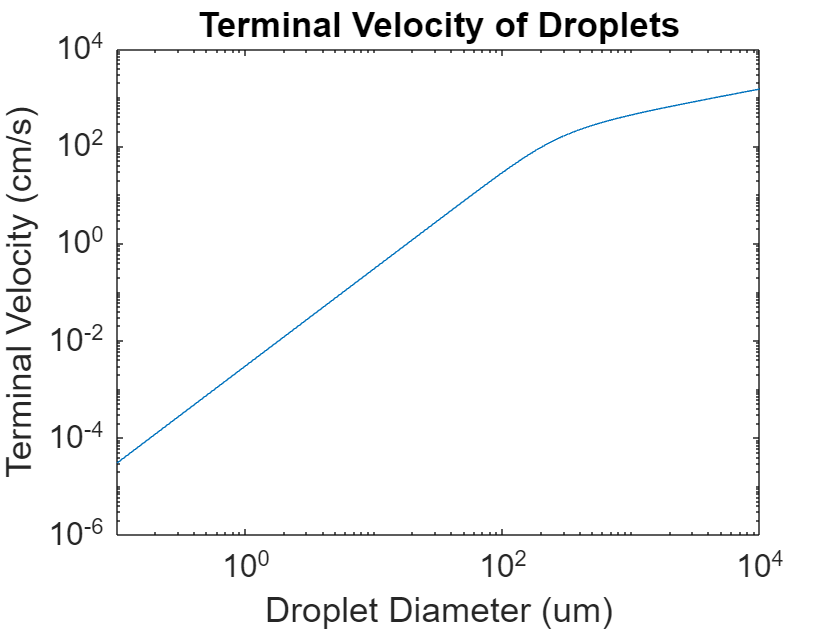

diameters_microns = logspace(-1, 4);
diameters = diameters_microns * 10^-6;
viscosity = 1.8*10^-5;
coefficient_of_drag = 0.47;
radius = diameters ./ 2;
volume = 4/3 * pi * radius.^3;
mass = volume * density_water;
area = pi * radius.^2;
b = 6 * pi * viscosity * radius;
c = 1/2 * coefficient_of_drag * density_air * area;
v = (b - sqrt(b.^2 + 4*c.*mass*g)) ./ (-2*c) * 100;
loglog(diameters_microns, v)
xlim([10^-1, 10^4])
set(gca, 'fontsize', 16)
xlabel('Droplet Diameter (um)')
title('Terminal Velocity of Droplets')
ylabel('Terminal Velocity (cm/s)')

**2.** 

A perfectly flexible chain has length L, mass M , and constant

mass per unit length $\frac{M}{L}$. At time t = 0 it is at rest with a length $x_0$ < L

hanging vertically over the edge of a table.

(i) Neglecting friction, compute the length x(t) hanging over the edge after

a time t. Assume that the horizontal and vertical sections remain straight

during the motion. At what time $t_L$ is x($t_L$) = L?

$m_2 =x\left(t\right)\left(\frac{M}{L}\right)$    -    Mass of hanging part of chain


$$m_1 =M-m_2 =\frac{M}{L}\left(L-x\left(t\right)\right)$$


$F_{\mathrm{net}} =m_2 g$    -    Only force acting upon the chain is the force of the mass hanging


$$m_2 g=\mathrm{Ma}$$


$a=\frac{m_2 g}{M}=\frac{x\left(t\right)\frac{M}{L}g}{M}=\frac{\mathrm{gx}\left(t\right)}{L}={x^{\prime } }^{\prime } \left(t\right)$    -    Differential

$x\left(t\right)={\mathrm{Ae}}^{\mathrm{ct}}$    -    Guess


$${x^{\prime } }^{\prime } \left(t\right)={\mathrm{Ac}}^2 e^{\mathrm{ct}}$$


$x\left(t\right)={\mathrm{Ae}}^{\sqrt{\frac{g}{L}t}} +{\mathrm{Be}}^{-\sqrt{\frac{g}{L}t}}$    -    Add negative part for posterity


$$x^{\prime } \left(t\right)=A\sqrt{\frac{g}{L}}e^{\sqrt{\frac{g}{L}t}} -B\sqrt{\frac{g}{L}}e^{-\sqrt{\frac{g}{L}}t}$$



$$x\left(0\right)=x_0 =A+B$$



$$x^{\prime } \left(0\right)=0=A\sqrt{\frac{g}{L}}-B\sqrt{\frac{g}{L}}$$



$$A-B=0$$



$$x\left(t\right)=\frac{x\left(0\right)}{2}e^{\sqrt{\frac{g}{L}}t} +\frac{x\left(0\right)}{2}e^{-\sqrt{\frac{g}{L}}t} =L$$



$$2\frac{L}{x\left(0\right)}=e^{\sqrt{\frac{g}{L}}t} +e^{-\sqrt{\frac{g}{L}}t} =e^{\sqrt{\frac{g}{L}}t} \left(1+e^{-2\sqrt{\frac{g}{L}}t} \right)$$



$$\frac{d}{\mathrm{dt}}\left(2\frac{L}{x\left(0\right)}e^{-\sqrt{\frac{g}{L}}t} =\left(1+e^{-2\sqrt{\frac{g}{L}}t} \right)\right)$$



$$\frac{L}{x\left(0\right)}e^{-\sqrt{\frac{g}{L}}t} =e^{-2\sqrt{\frac{g}{L}}t}$$



$$\begin{array}{l}
\frac{L}{x\left(0\right)}=e^{-\sqrt{\frac{g}{L}}t} \\
\ln \left(\frac{L}{x\left(0\right)}\right)=-\sqrt{\frac{g}{L}}t\\
t_L =-\sqrt{\frac{L}{g}}\cdot \ln \left(\frac{L}{x\left(0\right)}\right)
\end{array}$$


(ii) More realistically, there is a frictional force between the chain and table

top with kinetic and static coefficients of friction $\mu_k$< $\mu_s$. What is the max-

imum value of $x_0$, called $x_c$, such that the chain does not move?


$$F_{\mathrm{Net}} =F_{\mathrm{Friction}} +F_{\mathrm{gravity}} =0$$



$$F_{\mathrm{gravity}} =m_2 g$$


|$\begin{array}{l}
F_{\mathrm{drag}} |\le \mu_s N=\mu_s \left(m_1 \right)g\\
m_2 g=\mu_s \left(m_1 \right)g\Rightarrow x\left(t\right)\left(\frac{M}{L}\right)g=\mu_s \left(\frac{M}{L}\left(L-x\left(t\right)\right)\right)g
\end{array}$

(iii) At t = 0 and $x_0$ = $x_c$we give the chain a tiny velocity $v_i$ so that it

immediately begins to move and the coefficient of friction changes from $\mu_s$

to $\mu_k$. What now is the length hanging over the edge after a time t?

(You might want to try this out experimentally at home.)

3. (20 points) Consider a drag force that is linear in the velocity of an object

of mass m: Fdrag = −bv. The object is thrown with an initial velocity v0

that has nonzero components both horizontal and vertically upward.

(i) Derive the position of the object in both horizontal and vertical compo-

nents as a function of time.

(ii) Find the distance the object has moved in the horizontal direction after

three characteristic time constants have elapsed, that is when t = 3τ where

τ ≡ m/b.